# Alejandro Stawsky, Math 104C, Spring 2018, HW 


$$
\text{1.   }\\
\text{We must find the coefficients }a,\quad b,\quad c \text{ in the method } U^{n+1}=U^n+k(aF_0+bF_1+cF_2)\\
\text{such that it is third order.}\\
\text{We define two operators to simplify the algebra: }\\
D=\frac{\partial}{\partial u}f+\frac{\partial}{\partial t}, D^2=\frac{\partial^2}{\partial t^2}+2\frac{\partial^2}{\partial u \partial t}f+f^2\frac{\partial^2}{\partial u^2}\\
F_0=f(u(t_n),t_n)=f\\
F_1=f+\frac{1}{2}kDf+\frac{k^2}{8}D^2f+O(k^3)\\
F_2=f+\frac{3}{4}k(F_1f_u+f_t)+\frac{9k^2}{32}(F_1^2f_{uu}+2F_1f_{ut}+f_{tt})+O(k^3)\\
\text{now we will replace the first } F_1 \text{with its first two terms and the second and third }F_1 \text{ simply with its first term}\\
=f+\frac{3}{4}k((f+\frac{1}{2}kDf)f_u+f_t)+\frac{9k^2}{32}(f^2f_{uu}+2ff_{ut}+f_{tt})+O(k^3)\\
=f+\frac{3}{4}k(\frac{k}{2}Dff_u+Df)+\frac{9k^2}{32}(D^2f)+O(k^3)\\
=f+\frac{3}{4}kDf+k^2(\frac{9}{32}D^2f+\frac{3}{8}Dff_u)+O(k^3)\\
\text{notice that }\tau_n=\frac{u(t_{n+1})-u(t_n)}{k}-(aF_0+bF_1+cF_2)=(1)-(2)\\
(1)=u'+\frac{k}{2}u''+\frac{k^2}{6}u'''+O(k^3)=f+\frac{k}{2}Df+\frac{k^2}{6}(D^2f+f_uDf)+O(k^3)\\
(2)=f(a+b+c)+kDf(\frac{b}{2}+\frac{3c}{4})+k^2(b\frac{D^2f}{8}+c(\frac{3}{8}Dff_u+\frac{9}{32}D^2f))+O(k^3)\\
\Rightarrow \text{We get the system:}\\
a+b+c=1\\
\frac{b}{2}+\frac{3}{4}c=\frac{1}{2}\\
D^2f(\frac{1}{8}b+\frac{9}{32}c)+Dff_u(\frac{3}{8}c)=\frac{1}{6}(D^2f+f_uDf)\\
\Rightarrow \frac{3}{8}c=\frac{1}{6} \Rightarrow c=\frac{4}{9} \Rightarrow b=2(\frac{1}{2}-\frac{1}{3})=\frac{1}{3} \Rightarrow a=1-\frac{1}{3}-\frac{4}{9}=\frac{2}{9}\\
\Rightarrow u(t_{n+1})=u(t_n)+k(aF_0+bF_1+cF_2)=u(t_n)+k(\frac{2}{9}F_0+\frac{1}{3}F_1+\frac{4}{9}F_2)=u(t_n)+\frac{k}{9}(2F_0+3F_1+4F_2)_{QED}\\$$



$$\text{2.   }\\
U^{n+2}-\frac{3}{2}U^{n+1}+\frac{1}{2}U^n=k(\frac{5}{4}f^{n+1}-\frac{3}{4}f^n)\\
\tau_n=\frac{u(t_{n+2})-\frac{3}{2}u(t_{n+1})+\frac{1}{2}u(t_n)}{k}-\frac{5}{4}f(u_{n+1},t_{n+1})+\frac{3}{4}f(u_n,t_n)=(1)+(2)\\
(1)=\frac{u(t_{n+2})-\frac{3}{2}u(t_{n+1})+\frac{1}{2}u(t_n)}{k}=\frac{1}{2}u'+\frac{5}{4}ku''+\frac{13}{12}k^2u'''+...\\
(2)=-\frac{5}{4}f(u_{n+1},t_{n+1})+\frac{3}{4}f(u_n,t_n)=\frac{-1}{2}u'-\frac{5}{4}(ku''+\frac{k^2}{2}u'''+\frac{k^3}{6}u^{(4)}+...)\\
\Rightarrow\tau_n=(\frac{13}{12}-\frac{5}{8})k^2u'''+...=\frac{11}{24}k^2u'''+...=O(k^2)_{\text{ }QED}\\
\text{3.    }\\
U^{n+2}-3U^{n+1}+2U^n=k(\frac{1}{2}f^{n+1}-\frac{3}{2}f^n)\\
\tau_n=\frac{u_{n+2}-3u_{n+1}+2u_n}{k}-(\frac{1}{2}f^{n+1}-\frac{3}{2}f^n)\\
u(t_{n+2})=u+2ku'+\frac{4k^2}{2}u''+\frac{8k^3}{6}u'''+...\\
u(t_{n+1})=u+ku'+\frac{k^2}{2}u''+\frac{k^3}{6}u'''+...\\
\Rightarrow \frac{u(t_{n+2})-3u(t_{n+1})+2u}{k}=-u'+\frac{k}{2}u''+\frac{5k^2}{6}u'''+...\\
\frac{1}{2}f(u,t_{n+1})-\frac{3}{2}f(u,t_n)=-u'-\frac{1}{2}(u''k+\frac{u'''k^2}{2}+...)\\
\Rightarrow \tau_n=(\frac{5}{6}-\frac{1}{4})k^2u'''+...=\frac{7}{12}k^2u'''+...=O(k^2)_\text{ QED}\\$$


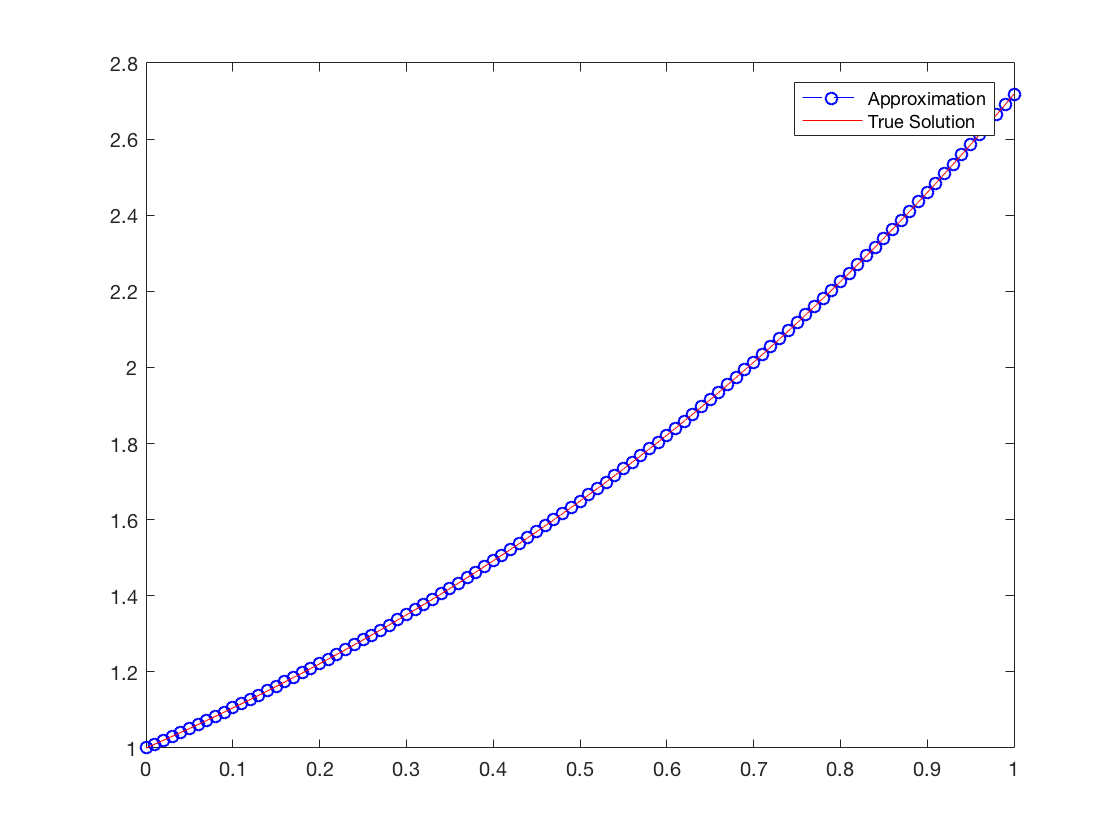

format long

% 4.

% % a. Problem 2 Method

k=.01; % length of step
T=1; % Distance
N=T/k; % Number of steps
U(1)=1; % initial condition
U(2)=exp(k); % initial condition

for i=2:N % method from problem 2
    U(i+1)=(3/2)*U(i)-(1/2)*U(i-1)+k*((5/4)*U(i)-(3/4)*U(i-1));
end
x=0:k:1; % approx points
figure();
plot(x,U,'b--o');
hold on
plot(x,exp(x),'r');
legend('Approximation','True Solution');
hold off

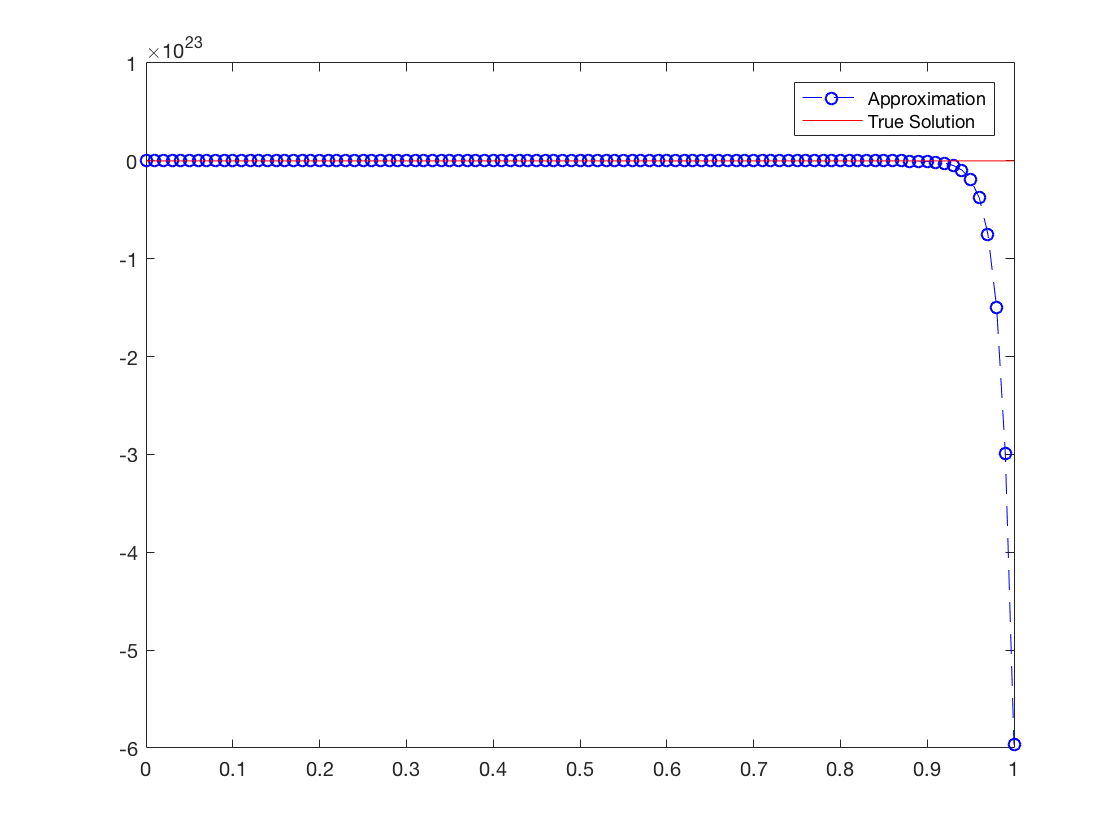


% % b. Problem 3 Method

for i=2:N % method from problem 3
    U(i+1)=(3)*U(i)-(2)*U(i-1)+k*((1/2)*U(i)-(3/2)*U(i-1));
end
x=0:k:1; % approx points
figure();
plot(x,U,'b--o');
hold on
plot(x,exp(x),'r');
legend('Approximation','True Solution');
hold off

## **c.**

Evidently method 2 converges while method 3 diverges, meaning method 2 is a better method. Looking at each methods' rho characteristic polynomial, $\rho \left(\xi \right)=\xi^2 -\frac{3}{2}\xi +\frac{1}{2}\text{ }\mathrm{and}\text{ }\rho \left(\xi \right)=\xi^2 -3\xi +2\text{ }$, respectively, we can deduce that the roots of the method from problem 2 are $\xi =1\text{ }\mathrm{and}\text{ }\frac{1}{2}$ while the ones for the method from problem 3 are $\xi =1\text{ }\text{and}\text{ }2$. The roots from the problem 2 method are both smaller in absolute value to 1, while the root $\xi =2$ from the problem 3 method is not smaller in absolute value to 1, implying that the method is therefore not zero-stable. This accounts for the divergence, becuase the initial step errors grow as $n\to \infty$.

5.


$$\begin{array}{l}
{\text{                                                      }\alpha }_0 =-1\\
{\text{ }U^{n+2} -U^n =2{\text{kf}}^{n+1} \text{ }\Rightarrow \text{     }\alpha }_1 =0\text{       }\Rightarrow \rho \left(\xi \right)=\xi^2 -1=0\Rightarrow \xi =\pm 1\\
\text{                                               }{\text{      }\alpha }_2 =1
\end{array}$$


Since these are two distinct roots whose absolute value is less than 1, the method on the left hand side is zero-stable.